
% Lab 3 for Digital Audio Signal Processing Lab Sessions
% Session 3: Noise reduction in the STFT domain
% R.Ali, G. Bernardi, J.Schott, A. Bertrand
% 2020
%
% The following is the skeleton code for doing the noise reduction in the
% STFT domain. Complete the missing sections accordingly
clear;
close all

if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
end

% Load ATFs
load Computed_RIRs

% load speech_both 
source_filename{1} = 'speech1.wav';
siglength = 4;
[source_signals_raw{1}, source_signals_raw{2}] = audioread(source_filename{1});
signal  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});
signal = 10*signal(1:siglength*fs_RIR);
speech = fftfilt(RIR_sources,signal,siglength*fs_RIR);


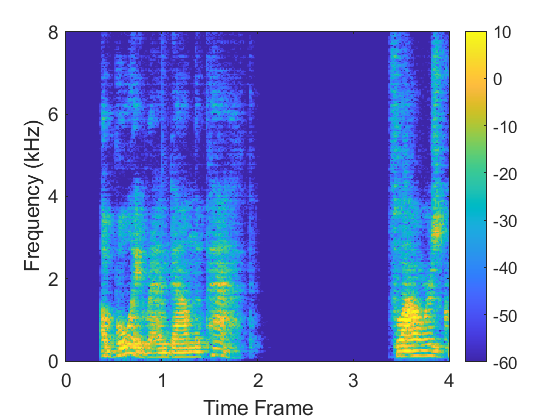


% Generate noise at microphone
SNR_bubble = 5; SNR_white = 30;
noise_filename{1} = 'Babble_noise1.wav';noise_filename{2} = 'White_noise1.wav';

noise_babble = generate_noise(noise_filename{1},speech(:,1),fs_RIR,SNR_bubble,RIR_noise,siglength);
noise_white  = generate_noise(noise_filename{2},speech(:,1),fs_RIR,SNR_white,RIR_noise,siglength);



%% Exercise 3.1: ## Obtain the noisy microphone signals as outlined in the session document.
%
% SOME CONVENTIONS:
%
% Your clean speech signal should be called "speech" and is a binaural signal such that:
% speech = [speech_L speech_R]  % speech_L and speech_R are the clean binaurally synthesised speech signals from session 1
%
% Your noises should be stored in one binaural variable called "noise"


noise = noise_white + noise_babble;
% noise = noise_babble;
% Create noisy mic signals in the time domain:
noisy_sig = speech + noise_babble;  % stacked microphone signals
%soundsc(y_TD,fs_RIR)
snrb = snr(speech(:,1),noise_babble(:,2));
snrw = snr(speech(:,1),noise_white(:,2));

%% Apply WOLA analysis to observe signals in the STFT domain, Apply the SPP.

fs = fs_RIR;    % sampling freq
nfft = 512;    % number of DFT points
window = sqrt(hann(nfft,'periodic')); % analysis window
noverlap = 2;   % factor for overlap. noverlap = 2 corresponds to 50% overlap
time = 0:1/fs:((size(speech,1)-1)/fs);


% ## Apply the WOLA analysis to the noisy mic. signals, the speech, and the noise.
[y_STFT,y_multi,f] = WOLA_analysis(noisy_sig,fs_RIR,window,nfft,noverlap) ;% To complete
[n_STFT,n_multi,~] = WOLA_analysis(noise,fs_RIR,window,nfft,noverlap) ;% To complete
[x_STFT,x_multi,~] = WOLA_analysis(speech,fs_RIR,window,nfft,noverlap) ;% To complete


% Observe the STFT
clow = -60; chigh = 10; % lower and upper limits for signal power in spectrogram (can change for different resolutions)
[N_freqs, N_frames] = size(y_STFT(:,:,1));

figure;
imagesc(time, f/1000, mag2db(abs(x_STFT(:,:,1))), [clow, chigh]); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')


% ## Compute the Speech Presence Probability on the reference microphone
% (you can try the speech-only signal or the noisy-speech in one of the microphones)
% Use the attached spp_calc.m function

% [noisePowMat, SPP] =  spp_calc888(y_STFT(:,:,1));% To complete
[noisePowMat, SPP] =  spp_calc(speech(:,1),nfft,nfft/noverlap);

函数或变量 'speech_rev' 无法识别。


% Observe the SPP
figure; subplot(2,1,1)
imagesc(1:N_frames, f,SPP); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');
  subplot(2,1,2)
  imagesc(1:N_frames, f/1000, mag2db(abs(x_STFT(:,:,1))), [clow, chigh]); colorbar;
  axis xy; set(gca,'fontsize', 14);
  set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)'),title('clean signal')

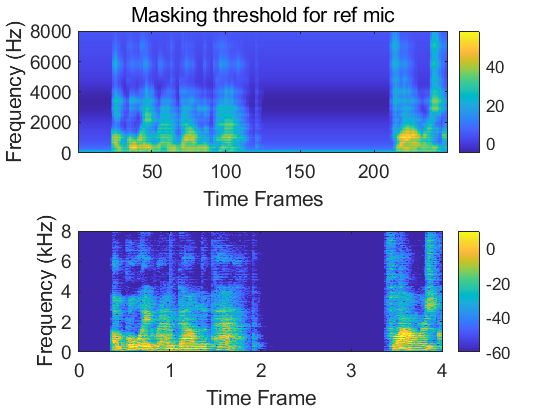


%%  calculat masking threshold
% 
TY_Mask = zeros(N_freqs,N_frames);
TX_Mask = zeros(N_freqs,N_frames);
TN_Mask = zeros(N_freqs,N_frames);
num_mics = 2;
%for m = 1:num_mics
  for t = 1:N_frames

    %  [TY_Mask(:,t),bark] = mask_cal(y_STFT(:,t,1),f,fs,nfft,t);
       [TX_Mask(:,t),bark] = mask_cal(x_multi(:,t,1),f,fs,nfft,t,5);
    %  [TN_Mask(:,t),bark] = mask_cal(n_STFT(:,t,1),f,fs,nfft,t);
      
  end
  figure; subplot(2,1,1)
  imagesc(1:N_frames, f,TX_Mask); colorbar; axis xy; set(gcf,'color','w');
  set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Masking threshold for ref mic');
  subplot(2,1,2)
  imagesc(time, f/1000, mag2db(abs(x_STFT(:,:,1))), [clow, chigh]); colorbar;
  axis xy; set(gca,'fontsize', 14);
  set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')

%%  Exercise 3.2: ## Implementation of the MWF
num_mics = 2;

Rnn = cell(N_freqs,1);  Rnn(:) = {1e-6*ones(num_mics,num_mics)};      % Noise Only (NO) corr. matrix. Initialize to small random values
Ryy = cell(N_freqs,1);  Ryy(:) = {1e-6*ones(num_mics,num_mics)};      % Speech + Noise (SPN) corr. matrix. Initialize to small random values
lambda = 0.995;                                                       % Forgetting factors for correlation matrices - can change
SPP_thr = 0.95;                                                       % Threshold for SPP - can change



% For MWF filter for left ear
S_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
X_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
N_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
W_mvdr_mwfL = (1/num_mics)*ones(num_mics,N_freqs,num_mics);




% STFT Processing
% Looping through each time frame and each frequency bin
tic
for l=1:N_frames % Time index
    
    for k = 1:N_freqs % Freq index
        model.mu = 1;
        mu = mu_calc(SPP(k,l),TX_Mask(k,l),NMR(k,l),model.mu);
        muxx(k,l) =  mu;    
        
        % Create a vector of mic. signals
        Y_kl = squeeze(y_STFT(k,l,1:num_mics));  % M x 1 noisy mic sigs for this freq and time frame
        X_kl = squeeze(x_STFT(k,l,1:num_mics));
        N_kl = squeeze(n_STFT(k,l,1:num_mics));
        
        % ## Update the correlation matrices using the forgetting factor.
        % Threshold the SPP in order to distinguish between periods of speech and non-speech activity
        if(SPP(k,l)>SPP_thr)
            Ryy{k} = lambda^2*Ryy{k}+(1-lambda^2).*Y_kl*Y_kl';
            % speech + noise
        else
            % noise only
            Rnn{k} = lambda^2*Rnn{k}+(1-lambda^2).*Y_kl*Y_kl'; % N*N' is not available in real situation 
        end
       
        
        % Computing the MWF filter using a generalised eigenvalue
        % decomposition of the correlation matrices.

        [V,d] = eig(Ryy{k},Rnn{k},'vector');
        [d,ind] = sort(d,'descend');
        V = V(:,ind);
        Qh = inv(V);
      
         for m = 1:num_mics
            % See DASP-CH4-37/40
            % d(1) corresponds to (d_noise/d_s&n)
            W_update = (1-mu/d(1)+mu-1)*Qh(1,1).*V(:,1);% Final expression for filter.
            % After experiments, we found that Filter parameter is not likely
            % larger than 2 if it converges.
            if(max(abs(W_update)) < 2.2)  % This will skip some initial frames  
                W_mvdr_mwfL(:,k,m) =W_update;  
            end
            % Filtering the noisy speech, the speech-only, and the noise-only.
          
            S_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* Y_kl(1:num_mics);
            X_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* X_kl(1:num_mics);
            N_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* N_kl(1:num_mics);
         end
        
        
    end % end freqs
end % end time frames
toc

历时 19.580372 秒。


%% Observe processed STFTs

% figure; imagesc(time,f/1000,mag2db(abs(y_STFT(:,:,1))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'), title('microphne signal, 1st mic');
% figure; imagesc(time,f/1000,mag2db(abs(S_mvdr_mwfL_stft(:,:,1))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'),title('Enhanced Signal L - MWF');


% %% Apply the synthesis stage of the WOLA framework to obtain the time domain equivalents:
% 
% s_mwfL = WOLA_synthesis(S_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of S_mvdr_mwfL_stft)
% x_mwfL = WOLA_synthesis(X_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of X_mvdr_mwfL_stft)
% n_mwfL = WOLA_synthesis(N_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of N_mvdr_mwfL_stft)
% 
% 
% % PLOT SIGNALS
% plot(real(s_mwfL));
% LISTEN TO SIGNALS!
%soundsc(s_mwfL,fs);
%  soundsc(noise_sig,fs);



%% EVALUATION

SNR_in_L =snr(speech(:,1),noise(:,1)); % Compute input SNR

SNR_out_L =snr(s_mwfL(:,1),n_mwfL(:,1)) ;% Compute output SNR
delta_SNR_L = SNR_out_L -SNR_in_L

delta_SNR_L = 2.2201

power_L=abs(y_STFT(:,:,1))./abs(S_mvdr_mwfL_stft(:,:,1));
power_L = power_L(:,3:N_frames);
SD_L = sum(sqrt(sum((10*log10(power_L)).^2,1)/N_freqs),2)/N_frames

SD_L = 7.7101

disp(['delta_SNR = ', num2str(delta_SNR_L),' ,SD_L is ', num2str(SD_L),' ,nfft is ', num2str(nfft)]);

delta_SNR = 2.2201 ,SD_L is 7.7101 ,nfft is 512
